close all
clear 
clc

tic
% The Reaction system is as follows:
% DNA ---> mRNA (Inside Nucleus only) (Rate Constant = k_transcription)
% mRNA ---> Protein (Inside Cytoplasm only) (Rate Constant = k_translation)
% mRNA ---> ∅ (degradation) (Inside Cytoplasm only) (Rate Constant = k_mRNA_deg_cytoplasm)
% Protein ---> ∅ (degradation) (Inside Cytoplasm only) (Rate Constant = k_protein_deg_cytoplasm)
% Substrate + Protein ---> S-P complex (Rate Constant = k_3)
% S-P Complex ---> mRNA + Protein (Rate Constant = k_4)

n = 15;
m = 5;

DNA_concentration = zeros(n,n);
mRNA_concentration = zeros(n,n);
Protein_concentration = zeros(n,n);

% Giving Initial Conditions and initializing rate constants
DNA_concentration(:,:) = 1;
Protein_concentration(:,:) = 20;
mRNA_concentration(:,:) = 10;

Diffusion_protein_cytoplasm = 0.01;
Diffusion_protein_nucleus = 0.01;

Diffusion_mRNA_cytoplasm = 0.1;
Diffusion_mRNA_nucleus = 0.01;

k_transport_mRNA_nc = 0.1;
k_transport_mRNA_cn = 0;
k_transport_protein_cn = 0.01;
k_transport_protein_nc = 0;
k_transcription = 0.1;
k_translation = 0.005;

k_mRNA_deg_cytoplasm = 0.001;
k_mRNA_deg_nucleus = 0.01;
k_protein_deg_cytoplasm = 0.01;
k_protein_deg_nucleus = 0.0001;
k_autopositive_feedback_protein = 0.01;
k_inhibition_transcription = 100;

left_boundary = 1:n:(n*n)-(n-1);
right_boundary = left_boundary + (n-1);
top_boundary = 1:n;
bottom_boundary = (n*n)-(n-1):n*n;

% Code to get the indices of only the nucleus
indices = reshape(1:(n*n), n, n)';
nucleus_indices = indices((n-m)/2+1:(n-m)/2+m, (n-m)/2+1:(n-m)/2+m);
inner_boundary_left_indices = nucleus_indices(:,1);
inner_boundary_top_indices = nucleus_indices(1,:);
inner_boundary_right_indices = nucleus_indices(:,m);
inner_boundary_bottom_indices = nucleus_indices(m,:);
outer_boundary_left_indices = inner_boundary_left_indices-1;
outer_boundary_top_indices = inner_boundary_top_indices-n;
outer_boundary_right_indices = inner_boundary_right_indices+1;
outer_boundary_bottom_indices = inner_boundary_bottom_indices+n;

i=1;
j=1;
time_end=20;
time(1)=0;

sum_concentration_mrna = zeros(20,1);
sum_concentration_protein = zeros(20,1);
sum_concentration_mrna(1) = sum(mRNA_concentration,"all");
sum_concentration_protein(1) = sum(Protein_concentration,"all");

mRNA_initial = sum(mRNA_concentration,"all");
fprintf('mRNA Concentration Total: %f',mRNA_initial);

mRNA Concentration Total: 2250.000000


Protein_initial = sum (Protein_concentration,"all");
fprintf('Protein Concentration Total: %f',Protein_initial);

Protein Concentration Total: 4500.000000

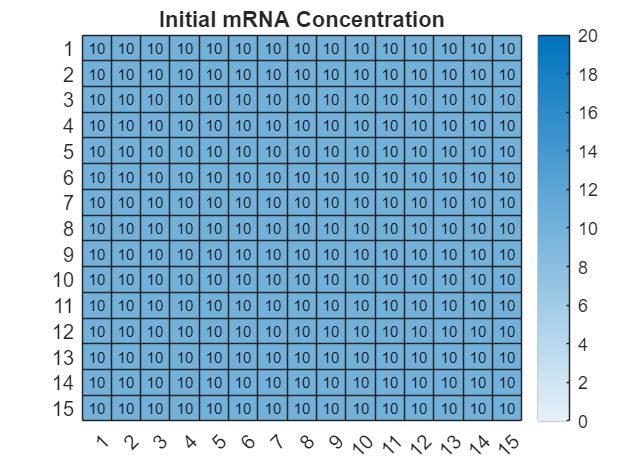

% Create figure and axes for the first heatmap

heatmap(mRNA_concentration);
title("Initial mRNA Concentration");
clim([0, 20]);

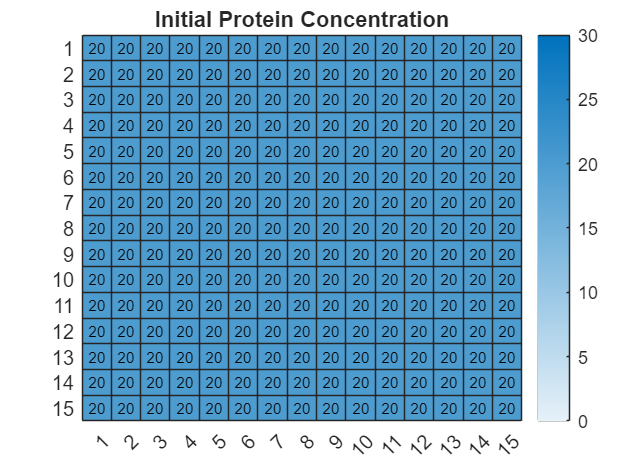

heatmap(Protein_concentration);
title("Initial Protein Concentration");
clim([0, 30]);

ri = [0:(n*n):(11*n*n)]; 


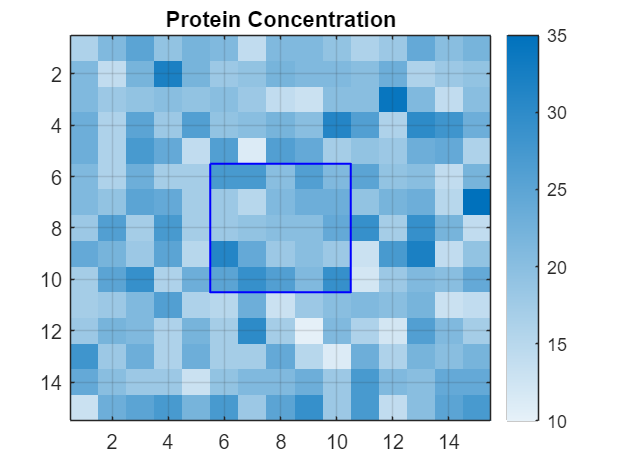

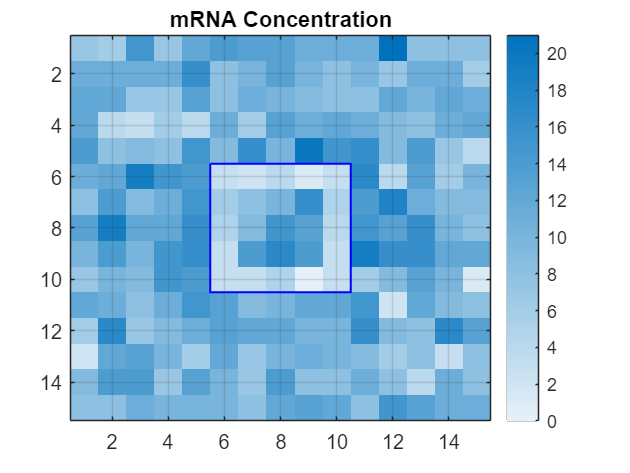

% Create figure and axes for the first heatmap
figure('Name', 'Heatmap 1 Animation');
heatmap1Ax = axes;
heatmap1 = imagesc(Protein_concentration);
title(heatmap1Ax, 'Protein Concentration');
colormap("sky")
% clim([0, 50]);
grid("on");
hold on;
plot([m+0.5, m+0.5, n-m+0.5, n-m+0.5, m+0.5], [m+0.5, n-m+0.5, n-m+0.5, m+0.5, m+0.5], 'blue', 'LineWidth', 1);
hold off;
colorbar;

% Create figure and axes for the second heatmap
figure('Name', 'Heatmap 2 Animation');
heatmap2Ax = axes;
heatmap2 = imagesc(mRNA_concentration);
title(heatmap2Ax, 'mRNA Concentration');
colormap("sky")
grid("on")
hold on;
plot([m+0.5, m+0.5, n-m+0.5, n-m+0.5, m+0.5], [m+0.5, n-m+0.5, n-m+0.5, m+0.5, m+0.5], 'blue', 'LineWidth', 1);
hold off;
% clim([0,100]);
colorbar;

% For Calculating Rate Propensities of Each Different Possible Reaction
while time(end)<time_end    
    Rate_propensities = zeros(1,(3*n*n)+8*(n*(n)));
    % Inside the Nucleus: Transcription of mRNA, Outside the Nucleus: Translation of mRNA into protein
    for i = 1 : ri(2)       
        if ismember(i,nucleus_indices)
            Rate_propensities(i) = k_transcription + Protein_concentration(row(ri,i,1,n),col(ri,i,1,n))/k_inhibition_transcription;
        else
            Rate_propensities(i) = k_translation            * mRNA_concentration(row(ri,i,1,n),col(ri,i,1,n)) + k_autopositive_feedback_protein * Protein_concentration(row(ri,i,1,n),col(ri,i,1,n));
        end
    end
    % Inside the Nucelus: Nothing; Outside the Nucleus: mRNA degradation
    for i = ri(2)+1 : ri(3) 
        if ismember(i-ri(2),nucleus_indices)  
            Rate_propensities(i) = k_mRNA_deg_nucleus       * mRNA_concentration(row(ri,i,2,n),col(ri,i,2,n));
        else
            Rate_propensities(i) = k_mRNA_deg_cytoplasm     * mRNA_concentration(row(ri,i,2,n),col(ri,i,2,n));
        end
    end
    % Inside the Nucelus: Nothing; Outside the Nucleus: protein degradation
    for i = ri(3)+1 : ri(4) 
        if ismember(i-ri(3),nucleus_indices)
            Rate_propensities(i) = k_protein_deg_nucleus    * Protein_concentration(row(ri,i,3,n),col(ri,i,3,n));          
        else
            Rate_propensities(i) = k_protein_deg_cytoplasm  * Protein_concentration(row(ri,i,3,n),col(ri,i,3,n));
        end
    end

    % Diffusion of mRNA from left to right
    for i = ri(4)+1 : ri(5)
        if ismember(i-ri(4),right_boundary)   
            Rate_propensities(i) = 0;
        elseif ismember(i-ri(4),outer_boundary_left_indices)        % Cytoplasm to Nucleus Diffusion
            Rate_propensities(i) = k_transport_mRNA_cn      * mRNA_concentration(row(ri,i,4,n),col(ri,i,4,n));
        elseif ismember(i-ri(4),inner_boundary_right_indices)       % Nucleus to Cytoplasm Diffusion
            Rate_propensities(i) = k_transport_mRNA_nc      * mRNA_concentration(row(ri,i,4,n),col(ri,i,4,n));
        elseif ismember(i-ri(4),nucleus_indices)                    % Within Nucleus Diffusion
            Rate_propensities(i) = Diffusion_mRNA_nucleus   * mRNA_concentration(row(ri,i,4,n),col(ri,i,4,n));
        else                                                        % Within Cytoplasm Diffusion
            Rate_propensities(i) = Diffusion_mRNA_cytoplasm * mRNA_concentration(row(ri,i,4,n),col(ri,i,4,n));
        end
    end
    % Diffusion of mRNA from right to left
    for i = ri(5)+1 : ri(6)
        if ismember(i-ri(5),left_boundary)   
            Rate_propensities(i) = 0;
        elseif ismember(i-ri(5),inner_boundary_left_indices)        % Nucleus to Cytoplasm Diffusion
            Rate_propensities(i) = k_transport_mRNA_nc      * mRNA_concentration(row(ri,i,5,n),col(ri,i,5,n));
        elseif ismember(i-ri(5),outer_boundary_right_indices)       % Cytoplasm to Nucleus Diffusion
            Rate_propensities(i) = k_transport_mRNA_cn      * mRNA_concentration(row(ri,i,5,n),col(ri,i,5,n));
        elseif ismember(i-ri(5),nucleus_indices)                    % Within Nucleus Diffusion
            Rate_propensities(i) = Diffusion_mRNA_nucleus   * mRNA_concentration(row(ri,i,5,n),col(ri,i,5,n));
        else                                                        % Within Cytoplasm Diffusion
            Rate_propensities(i) = Diffusion_mRNA_cytoplasm * mRNA_concentration(row(ri,i,5,n),col(ri,i,5,n));
        end
    end
    % Diffusion of mRNA from Up to Down
    for i = ri(6)+1 : ri(7)
        if ismember(i-ri(6),bottom_boundary)   
            Rate_propensities(i) = 0;
        elseif ismember(i-ri(6),outer_boundary_top_indices)         % Cytoplasm to Nucleus Diffusion
            Rate_propensities(i) = k_transport_mRNA_cn      * mRNA_concentration(row(ri,i,6,n),col(ri,i,6,n));
        elseif ismember(i-ri(6),inner_boundary_bottom_indices)      % Nucleus to Cytoplasm Diffusion
            Rate_propensities(i) = k_transport_mRNA_nc      * mRNA_concentration(row(ri,i,6,n),col(ri,i,6,n));
        elseif ismember(i-ri(6),nucleus_indices)                    % Within Nucleus Diffusion
            Rate_propensities(i) = Diffusion_mRNA_nucleus   * mRNA_concentration(row(ri,i,6,n),col(ri,i,6,n));
        else                                                        % Within Cytoplasm Diffusion
            Rate_propensities(i) = Diffusion_mRNA_cytoplasm * mRNA_concentration(row(ri,i,6,n),col(ri,i,6,n));
        end
    end
    % Diffusion of mRNA from Down to Up
    for i = ri(7)+1 : ri(8)
        if ismember(i-ri(7),top_boundary)   
            Rate_propensities(i) = 0;
        elseif ismember(i-ri(7),inner_boundary_top_indices)         % Nucleus to Cytoplasm Diffusion
            Rate_propensities(i) = k_transport_mRNA_nc      * mRNA_concentration(row(ri,i,7,n),col(ri,i,7,n));
        elseif ismember(i-ri(7),outer_boundary_bottom_indices)      % Cytoplasm to Nucleus Diffusion
            Rate_propensities(i) = k_transport_mRNA_cn      * mRNA_concentration(row(ri,i,7,n),col(ri,i,7,n));
        elseif ismember(i-ri(7),nucleus_indices)                    % Within Nucleus Diffusion
            Rate_propensities(i) = Diffusion_mRNA_nucleus   * mRNA_concentration(row(ri,i,7,n),col(ri,i,7,n));
        else                                                        % Within Cytoplasm Diffusion
            Rate_propensities(i) = Diffusion_mRNA_cytoplasm * mRNA_concentration(row(ri,i,7,n),col(ri,i,7,n));
        end
    end
    
    % Diffusion of Protein from left to right
    for i = ri(8)+1 : ri(9)
        if ismember(i-ri(8),right_boundary)   
            Rate_propensities(i) = 0;
        elseif ismember(i-ri(8),outer_boundary_left_indices)        % Cytoplasm to Nucleus Diffusion
            Rate_propensities(i) = k_transport_protein_cn       * Protein_concentration(row(ri,i,8,n),col(ri,i,8,n));
        elseif ismember(i-ri(8),inner_boundary_right_indices)       % Nucleus to Cytoplasm Diffusion
            Rate_propensities(i) = k_transport_protein_nc       * Protein_concentration(row(ri,i,8,n),col(ri,i,8,n));
        elseif ismember(i-ri(8),nucleus_indices)                    % Within Nucleus Diffusio
            Rate_propensities(i) = Diffusion_protein_nucleus    * Protein_concentration(row(ri,i,8,n),col(ri,i,8,n));
        else                                                        % Within Cytoplasm Diffusion
            Rate_propensities(i) = Diffusion_protein_cytoplasm  * Protein_concentration(row(ri,i,8,n),col(ri,i,8,n));
        end
    end
    % Diffusion of Protein from right to left
    for i = ri(9)+1 : ri(10)
        if ismember(i-ri(9),left_boundary)   
            Rate_propensities(i) = 0;
        elseif ismember(i-ri(9),inner_boundary_left_indices)        % Nucleus to Cytoplasm Diffusion
            Rate_propensities(i) = k_transport_protein_nc       * Protein_concentration(row(ri,i,9,n),col(ri,i,9,n));
        elseif ismember(i-ri(9),outer_boundary_right_indices)       % Cytoplasm to Nucleus Diffusion
            Rate_propensities(i) = k_transport_protein_cn       * Protein_concentration(row(ri,i,9,n),col(ri,i,9,n));
        elseif ismember(i-ri(9),nucleus_indices)                    % Within Nucleus Diffusion
            Rate_propensities(i) = Diffusion_protein_nucleus    * Protein_concentration(row(ri,i,9,n),col(ri,i,9,n));
        else                                                        % Within Cytoplasm Diffusion
            Rate_propensities(i) = Diffusion_protein_cytoplasm  * Protein_concentration(row(ri,i,9,n),col(ri,i,9,n));
        end
    end
    % Diffusion of Product from Up to Down
    for i = ri(10)+1 : ri(11)
        if ismember(i-ri(10),bottom_boundary)   
            Rate_propensities(i) = 0;
        elseif ismember(i-ri(10),outer_boundary_top_indices)        % Cytoplasm to Nucleus Diffusion
            Rate_propensities(i) = k_transport_protein_cn       * Protein_concentration(row(ri,i,10,n),col(ri,i,10,n));
        elseif ismember(i-ri(10),inner_boundary_bottom_indices)     % Nucleus to Cytoplasm Diffusion
            Rate_propensities(i) = k_transport_protein_nc       * Protein_concentration(row(ri,i,10,n),col(ri,i,10,n));
        elseif ismember(i-ri(10),nucleus_indices)                   % Within Nucleus Diffusion
            Rate_propensities(i) = Diffusion_protein_nucleus    * Protein_concentration(row(ri,i,10,n),col(ri,i,10,n));
        else                                                        % Within Cytoplasm Diffusion
            Rate_propensities(i) = Diffusion_protein_cytoplasm  * Protein_concentration(row(ri,i,10,n),col(ri,i,10,n));
        end
    end
    % Diffusion of Product from Down to Up
    for i = ri(11)+1 : ri(12)
        if ismember(i-ri(11),top_boundary)   
            Rate_propensities(i) = 0;
        elseif ismember(i-ri(11),inner_boundary_top_indices)        % Nucleus to Cytoplasm Diffusion
            Rate_propensities(i) = k_transport_protein_nc       * Protein_concentration(row(ri,i,11,n),col(ri,i,11,n));
        elseif ismember(i-ri(11),outer_boundary_bottom_indices)     % Cytoplasm to Nucleus Diffusion
            Rate_propensities(i) = k_transport_protein_cn       * Protein_concentration(row(ri,i,11,n),col(ri,i,11,n));
        elseif ismember(i-ri(11),nucleus_indices)                   % Within Nucleus Diffusion
            Rate_propensities(i) = Diffusion_protein_nucleus    * Protein_concentration(row(ri,i,11,n),col(ri,i,11,n));
        else                                                        % Within Cytoplasm Diffusion
            Rate_propensities(i) = Diffusion_protein_cytoplasm  * Protein_concentration(row(ri,i,11,n),col(ri,i,11,n));
        end
    end
        
    rate_sum = sum(Rate_propensities);
    cumulative_rate_sum = cumsum(Rate_propensities);

    % Calculating the Time Steps for each reaction occuring
    r1=rand(1);
    tau = -log(r1)/rate_sum;
    time(j+1)=time(j)+tau;

    % For Stochastically choosing a random index for each time step
    r2 = rand();
    index = 0;
    for k=1:ri(12)
        if r2*rate_sum <= cumulative_rate_sum(1)
            index=1;
            break;
        elseif r2*rate_sum <= cumulative_rate_sum(k+1) && r2*rate_sum > cumulative_rate_sum(k)
            index=k+1;
            break;
        end
    end
    % Chooses a Reaction depending on the index chosen above and then
    % Performs that Reaction
    if  index > ri(1) && index <= ri(2) % Inside the Nucleus: Transcription of mRNA, Outside the Nucleus: Translation of mRNA into protein
        if ismember(index,nucleus_indices)
            mRNA_concentration(row(ri,index,1,n),col(ri,index,1,n)) = mRNA_concentration(row(ri,index,1,n),col(ri,index,1,n)) + 1;
        else
            Protein_concentration(row(ri,index,1,n),col(ri,index,1,n)) = Protein_concentration(row(ri,index,1,n),col(ri,index,1,n)) + 1;
        end

    elseif index > ri(2) && index <= ri(3)      % mRNA degradation
        mRNA_concentration(row(ri,index,2,n),col(ri,index,2,n)) = mRNA_concentration(row(ri,index,2,n),col(ri,index,2,n)) - 1;

    elseif index > ri(3) && index <= ri(4)      % Protein degradation
        Protein_concentration(row(ri,index,3,n),col(ri,index,3,n)) = Protein_concentration(row(ri,index,3,n),col(ri,index,3,n)) - 1;

    elseif index > ri(4) && index <= ri(5)      % Diffusion of mRNA from left to right
        mRNA_concentration(row(ri,index,4,n),col(ri,index,4,n)) = mRNA_concentration(row(ri,index,4,n),col(ri,index,4,n)) - 1;
        mRNA_concentration(row(ri,index,4,n),col(ri,index,4,n)+1) = mRNA_concentration(row(ri,index,4,n),col(ri,index,4,n)+1) + 1;

    elseif index > ri(5) && index <= ri(6)      % Diffusion of mRNA from right to left
        mRNA_concentration(row(ri,index,5,n),col(ri,index,5,n)) = mRNA_concentration(row(ri,index,5,n),col(ri,index,5,n)) - 1;
        mRNA_concentration(row(ri,index,5,n),col(ri,index,5,n)-1) = mRNA_concentration(row(ri,index,5,n),col(ri,index,5,n)-1) + 1;

    elseif index > ri(6) && index <= ri(7)      % Diffusion of mRNA from up to down
        mRNA_concentration(row(ri,index,6,n),col(ri,index,6,n)) = mRNA_concentration(row(ri,index,6,n),col(ri,index,6,n)) - 1;
        mRNA_concentration(row(ri,index,6,n)+1,col(ri,index,6,n)) = mRNA_concentration(row(ri,index,6,n)+1,col(ri,index,6,n)) + 1;
   
    elseif index > ri(7) && index <= ri(8)      % Diffusion of mRNA from down to up
        mRNA_concentration(row(ri,index,7,n),col(ri,index,7,n)) = mRNA_concentration(row(ri,index,7,n),col(ri,index,7,n)) - 1;
        mRNA_concentration(row(ri,index,7,n)-1,col(ri,index,7,n)) = mRNA_concentration(row(ri,index,7,n)-1,col(ri,index,7,n)) + 1;
    
    elseif index > ri(8) && index <= ri(9)      % Diffusion of Protein from left to right
        Protein_concentration(row(ri,index,8,n),col(ri,index,8,n)) = Protein_concentration(row(ri,index,8,n),col(ri,index,8,n)) - 1;
        Protein_concentration(row(ri,index,8,n),col(ri,index,8,n)+1) = Protein_concentration(row(ri,index,8,n),col(ri,index,8,n)+1) + 1;
    
    elseif index > ri(9) && index <= ri(10)     % Diffusion of Protein from right to left
        Protein_concentration(row(ri,index,9,n),col(ri,index,9,n)) = Protein_concentration(row(ri,index,9,n),col(ri,index,9,n)) - 1;
        Protein_concentration(row(ri,index,9,n),col(ri,index,9,n)-1) = Protein_concentration(row(ri,index,9,n),col(ri,index,9,n)-1) + 1;

    elseif index > ri(10) && index <= ri(11)    % Diffusion of Protein from up to down
        Protein_concentration(row(ri,index,10,n),col(ri,index,10,n)) = Protein_concentration(row(ri,index,10,n),col(ri,index,10,n)) - 1;
        Protein_concentration(row(ri,index,10,n)+1,col(ri,index,10,n)) = Protein_concentration(row(ri,index,10,n)+1,col(ri,index,10,n)) + 1;

    elseif index > ri(11) && index <= ri(12)    % Diffusion of Protein from down to up
        Protein_concentration(row(ri,index,11,n),col(ri,index,11,n)) = Protein_concentration(row(ri,index,11,n),col(ri,index,11,n)) - 1;
        Protein_concentration(row(ri,index,11,n)-1,col(ri,index,11,n)) = Protein_concentration(row(ri,index,11,n)-1,col(ri,index,11,n)) + 1;

    end
    if mod(j,50) == 0
        set(heatmap1, 'CData', Protein_concentration);
        set(heatmap2, 'CData', mRNA_concentration);
        pause(0.01);
    end
    sum_concentration_mrna(j+1) = sum(mRNA_concentration,"all");
    sum_concentration_protein(j+1) = sum(Protein_concentration,"all");
    j=j+1;
end

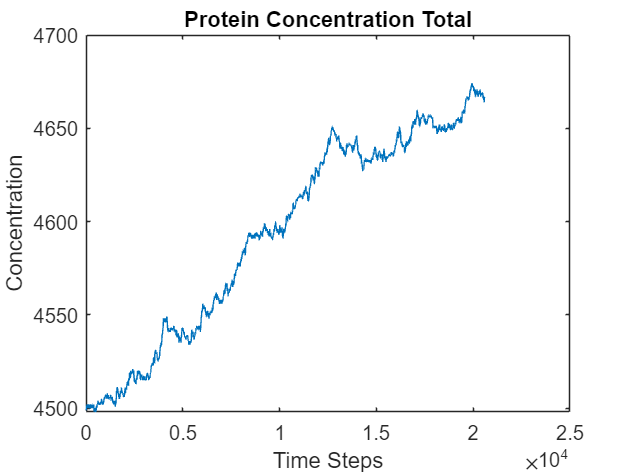


plot(sum_concentration_protein);
title("Protein Concentration Total")
ylabel("Concentration");
xlabel("Time Steps");

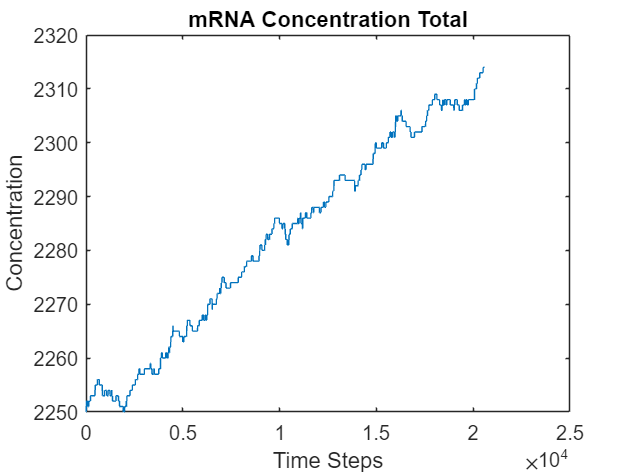

plot(sum_concentration_mrna);
title("mRNA Concentration Total")
ylabel("Concentration");
xlabel("Time Steps");

toc

Elapsed time is 92.285552 seconds.


function row_call = row(ri,index,k,n)
    row_call = ceil((index-ri(k))/n);
end
function column_call = col(ri,index,k,n)
    column_call = (n * (rem(index-ri(k),n)==0)) + rem((index-ri(k)),n);
end
% function increment_value = increment(increment_value)
%     increment_value = increment_value + 1;
% end
% function decrement_value = decrement(decrement_value)
%     decrement_value = decrement_value - 1;
% end